clf;
clear;

Lena = imread("../materials/Lena.tif");
size(Lena)

ans =    256   256


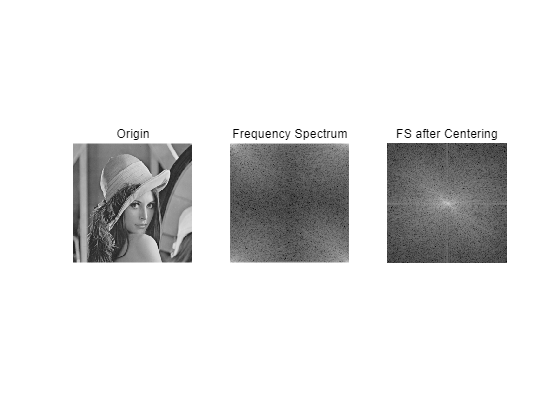

subplot(1,3,1);
imshow(Lena);title('Origin');

Lena = im2double(im2gray(Lena));
FFT_Lena = my_fft(Lena);
%FFT_Lena = fft2(Lena); %check
FS_Lena = log(abs(FFT_Lena)); % log compress
%imshow(FFT_Lena);title('After FFT');
subplot(1,3,2);
imshow(FS_Lena,[]);title('Frequency Spectrum');

FFTSHIFT_Lena = my_fftshift(FFT_Lena); %FFT centering
%FFTSHIFT_Lena=fftshift(FFT_Lena); %check
FSSHIFT_Lena = log(abs(FFTSHIFT_Lena)); % log compress
subplot(1,3,3);
imshow(FSSHIFT_Lena,[]);title('FS after Centering');

function out = my_fft(image)
    [M, N] = size(image);
    m = zeros(M, M);
    n = zeros(N, N);
    
    for u = 0:(M-1)
        for x = 0:(M-1)
            m(u+1, x+1) = exp(-2*pi*1i/M*x*u);
        end    
    end
    
    for v = 0:(N-1)
        for y = 0:(N-1)
            n(y+1, v+1) = exp(-2*pi*1i/N*y*v);
        end    
    end
    
    out = m*im2double(image)*n;
end

% fftshift
function out=my_fftshift(image)
    [M,N] = size(image);
    m = ceil(M/2);
    n = ceil(N/2);

    % horizontal
    tmp1=zeros(M,n);
    tmp2=zeros(M,N-n);
    tmp1(:,:) = image(:,1:n);
    tmp2(:,:) = image(:,n+1:N);
    image(:,1:N-n) = tmp2;
    image(:,N-n+1:N) = tmp1;

    % vertical
    tmp1 = zeros(m,N);
    tmp2 = zeros(M-m,N);
    tmp1(:,:) = image(1:m,:);
    tmp2(:,:) = image(m+1:M,:);
    image(1:M-m,:) = tmp2;
    image(M-m+1:M,:) = tmp1;

    out = image;
end